Simulation of ACh sensor that should go to the paper.

% give this simulation a name
SimulationName='simulation_ACh_20221221';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/';

% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation/simulation_ACh_20221221/'

cd(filepath)

datapath = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/'

datapath = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/'

stateYao_file = "/Volumes/yaochen/Active/Pingchuan/2022Fall/20220914AChsensorHEK001/analysis_offset0/20220914AChsensorHEK001_Analysis2022-09-23.mat"

stateYao_file = "/Volumes/yaochen/Active/Pingchuan/2022Fall/20220914AChsensorHEK001/analysis_offset0/20220914AChsensorHEK001_Analysis2022-09-23.mat"


all_epochs = [2 3 4 5 6]; % all the epochs
drug_epochs = [2 3 4 5 6];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

cd(datapath);
load(stateYao_file);

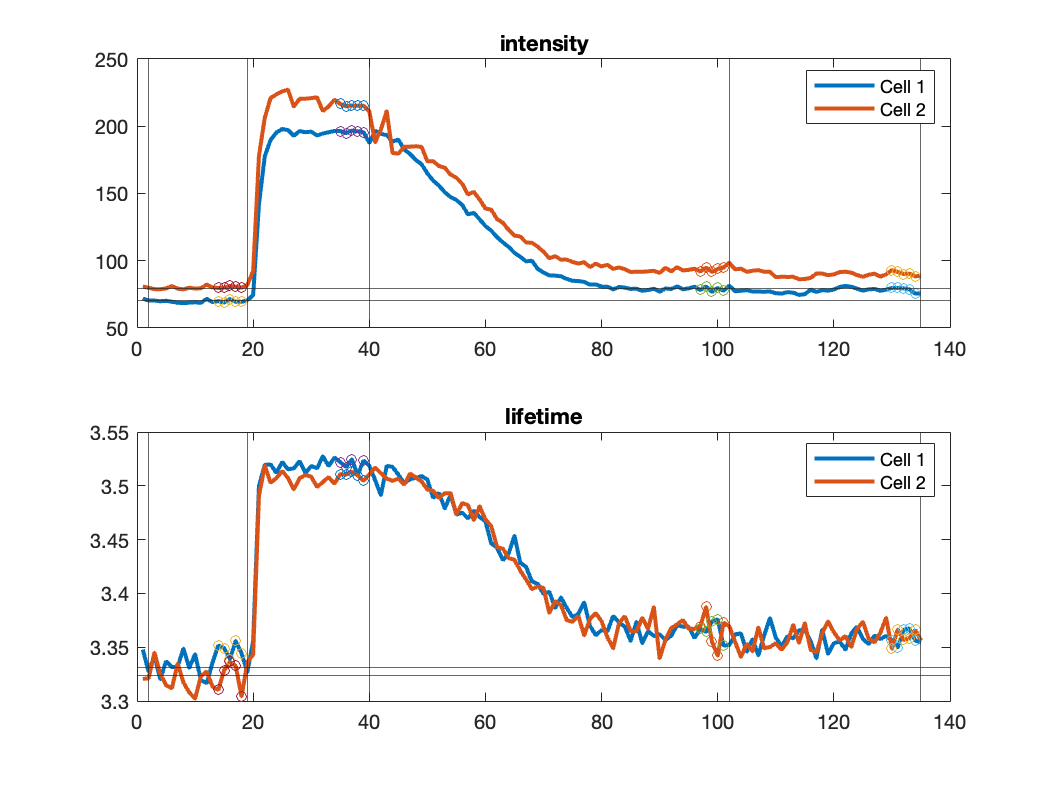

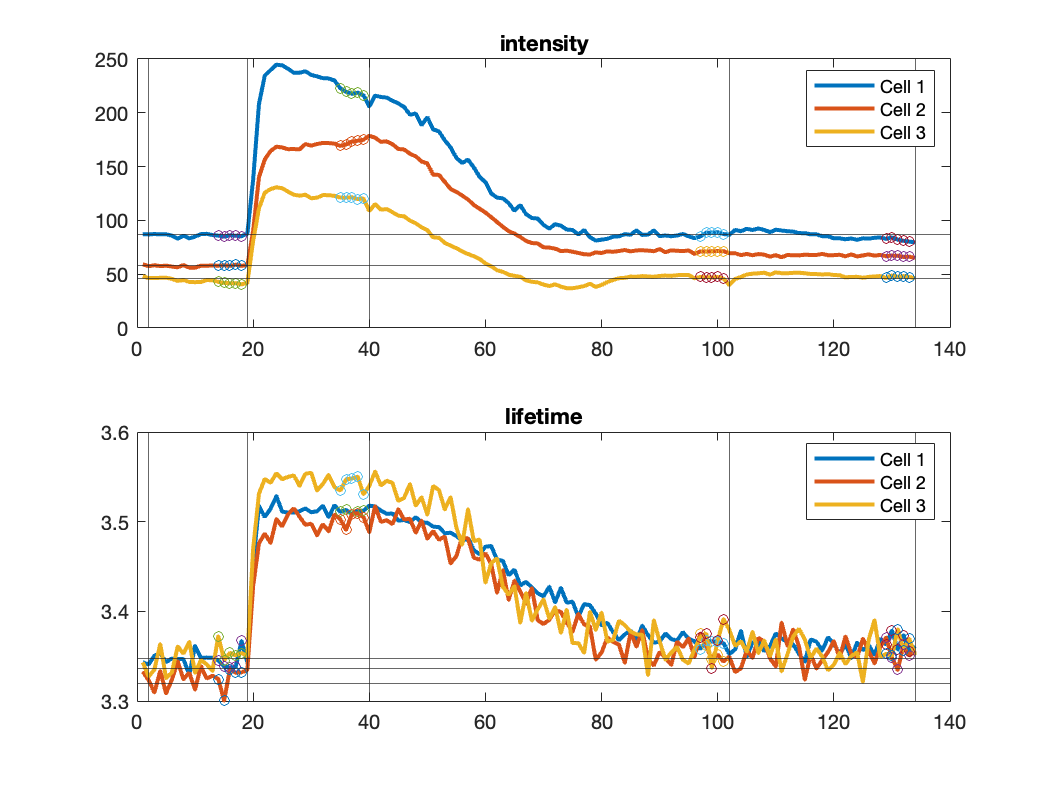

epoch_response_intensity_norm_all = 1×2 cell array
    {4×2 double}    {4×3 double}


epoch_response_lft_norm_all = 1×2 cell array
    {4×2 double}    {4×3 double}


epoch_response_intensity_all = 1×2 cell array
    {4×2 double}    {4×3 double}


epoch_response_lft_all = 1×2 cell array
    {4×2 double}    {4×3 double}


Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
CalculateROIBasedOnTopPixels(5, 0.66,CyclePositions)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

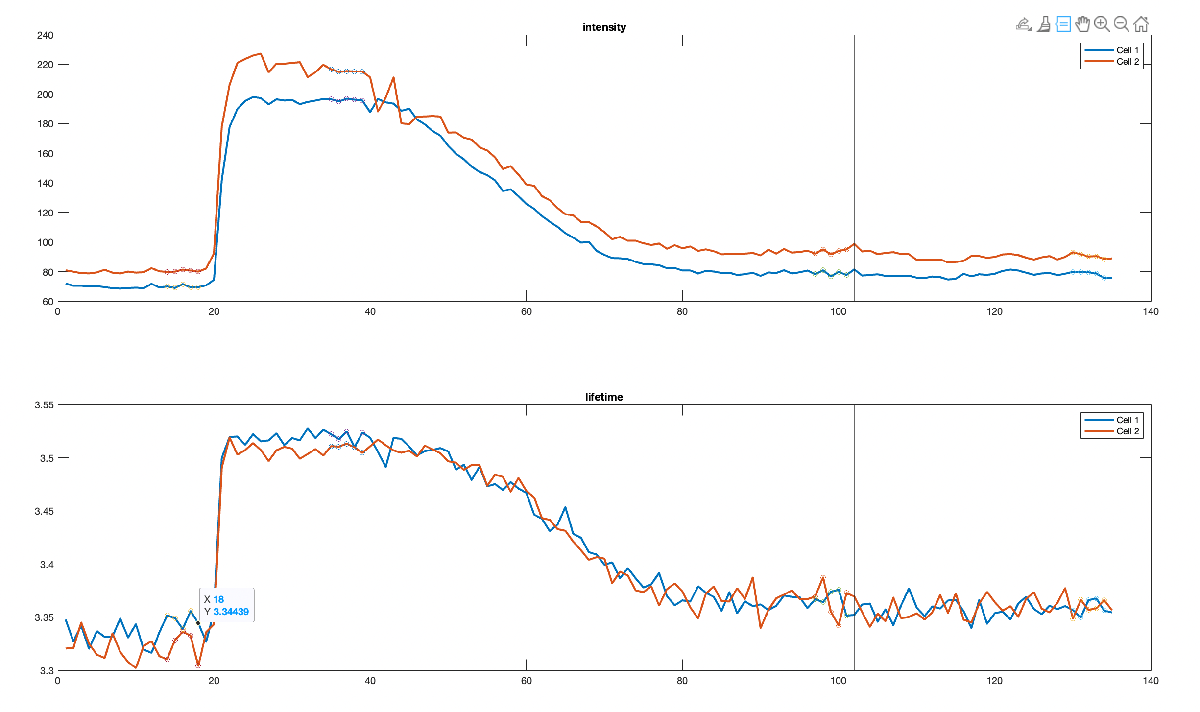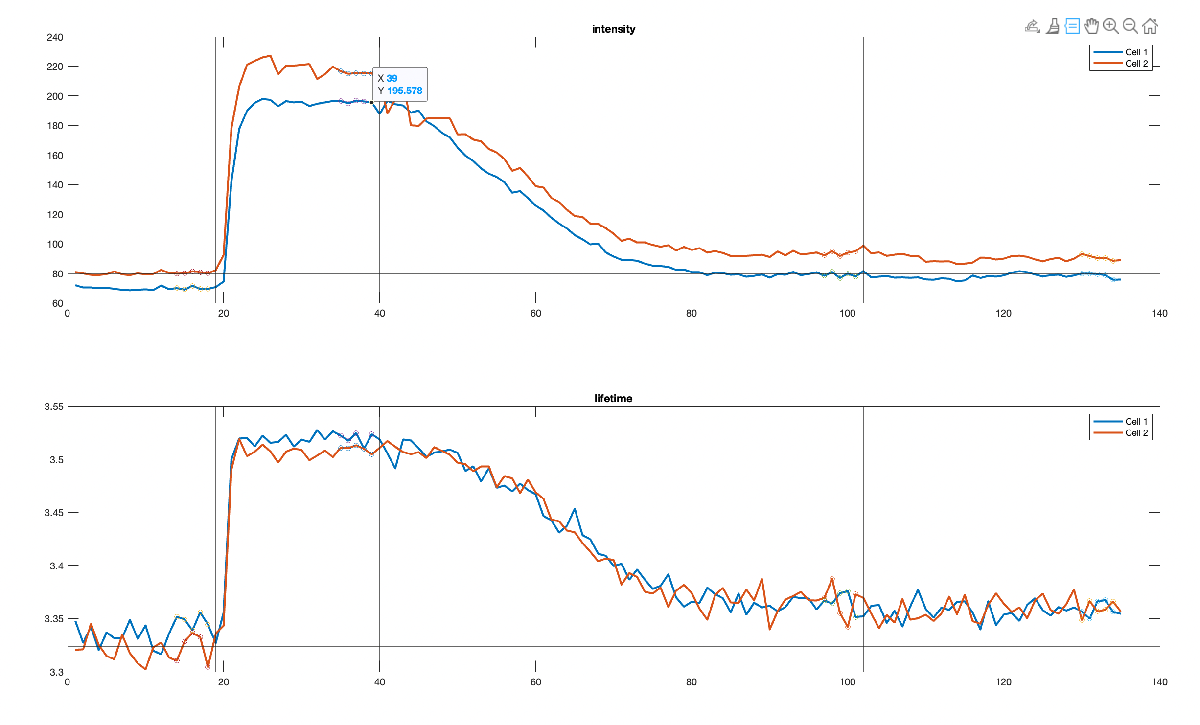

baseline_index_cycle1 = 18;
ACh_index_cycle1 = 39;
baseline_index_cycle2 = 18;
ACh_index_cycle2 = 39;
baseline_acq_cycle1 = stateYao.CyclePositions(baseline_index_cycle1,1)

baseline_acq_cycle1 = 40

ACh_acq_cycle1 = stateYao.CyclePositions(ACh_index_cycle1,1)

ACh_acq_cycle1 = 82

baseline_acq_cycle2 = stateYao.CyclePositions(baseline_index_cycle2,2)

baseline_acq_cycle2 = 41

ACh_acq_cycle2 = stateYao.CyclePositions(ACh_index_cycle2,2)

ACh_acq_cycle2 = 83

% load the file of ACh sensor under ACh 100 uM condition
ACh_spc_file_cycle1 = [datapath stateYao.baseName 'FLIM0' num2str(ACh_acq_cycle1) '.mat']

ACh_spc_file_cycle1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/20220914AChsensorHEK001FLIM082.mat'

spc_openCurves(ACh_spc_file_cycle1)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/20220914AChsensorHEK001FLIM082.mat


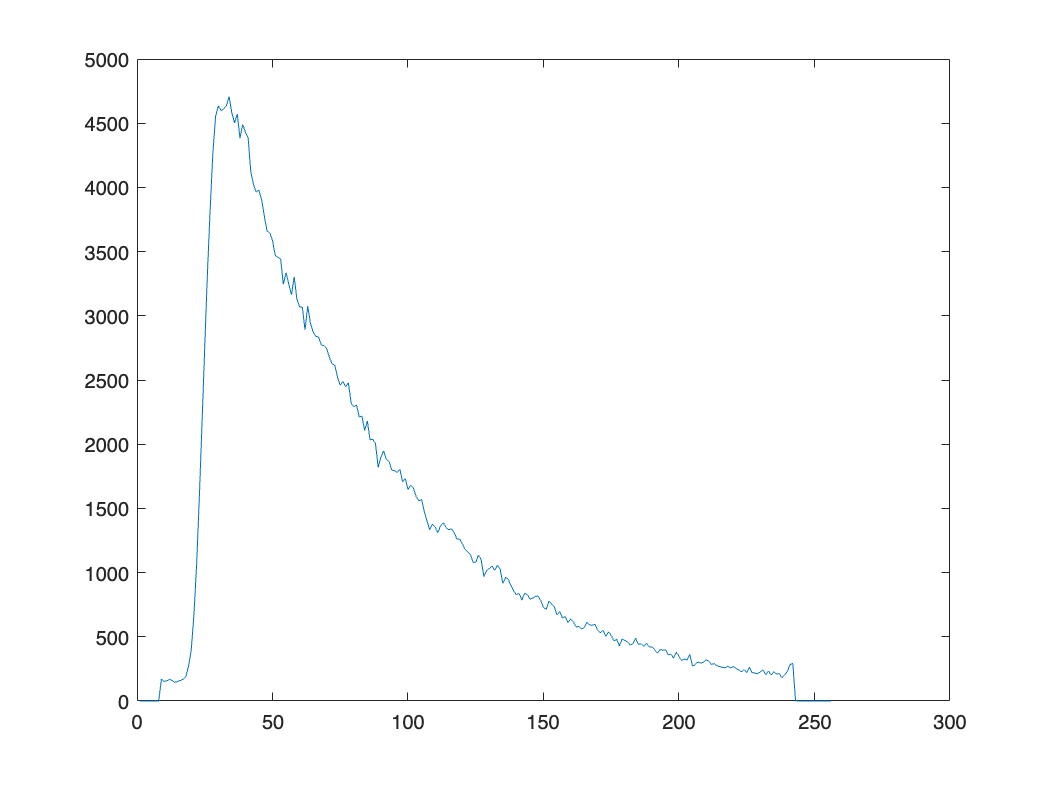

spc_lifetimes_cycle1 = zeros(256,1);
for iCell = 1:size(stateYao.images.I_ROI_stack{1}{ACh_index_cycle1},3)
    mask = stateYao.images.I_ROI_stack{1}{ACh_index_cycle1}(:,:,iCell);
    for i_x = 1:128
        for i_y = 1:128
            if mask(i_x,i_y)==1
                spc_lifetimes_cycle1 = spc_lifetimes_cycle1 + spc.imageMods{1}(:,i_x, i_y);
            end
        end
    end
end

figure
plot(spc_lifetimes_cycle1)

ACh_spc_file_cycle2 = [datapath stateYao.baseName 'FLIM0' num2str(ACh_acq_cycle2) '.mat']

ACh_spc_file_cycle2 = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/20220914AChsensorHEK001FLIM083.mat'

spc_openCurves(ACh_spc_file_cycle2)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/20220914AChsensorHEK001FLIM083.mat


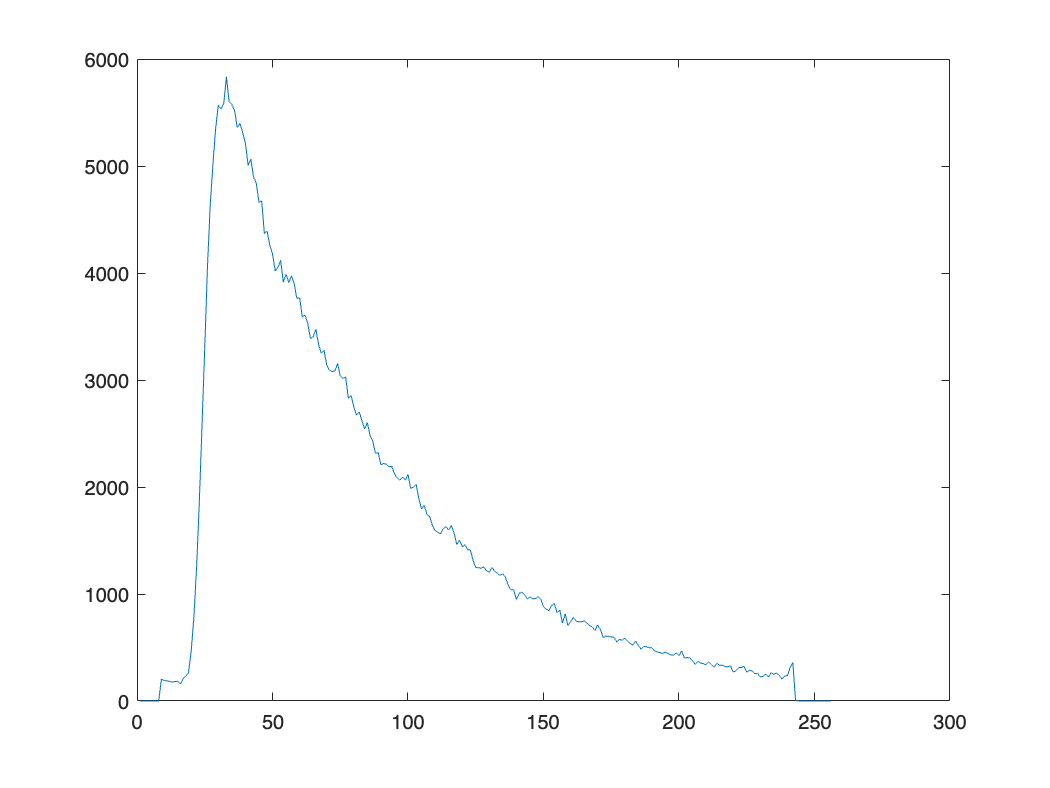

spc_lifetimes_cycle2 = zeros(256,1);
for iCell = 1:size(stateYao.images.I_ROI_stack{2}{ACh_index_cycle1},3)
    mask = stateYao.images.I_ROI_stack{2}{ACh_index_cycle2}(:,:,iCell);
    for i_x = 1:128
        for i_y = 1:128
            if mask(i_x,i_y)==1
                spc_lifetimes_cycle2 = spc_lifetimes_cycle2 + spc.imageMods{1}(:,i_x, i_y);
            end
        end
    end
end

figure
plot(spc_lifetimes_cycle2)

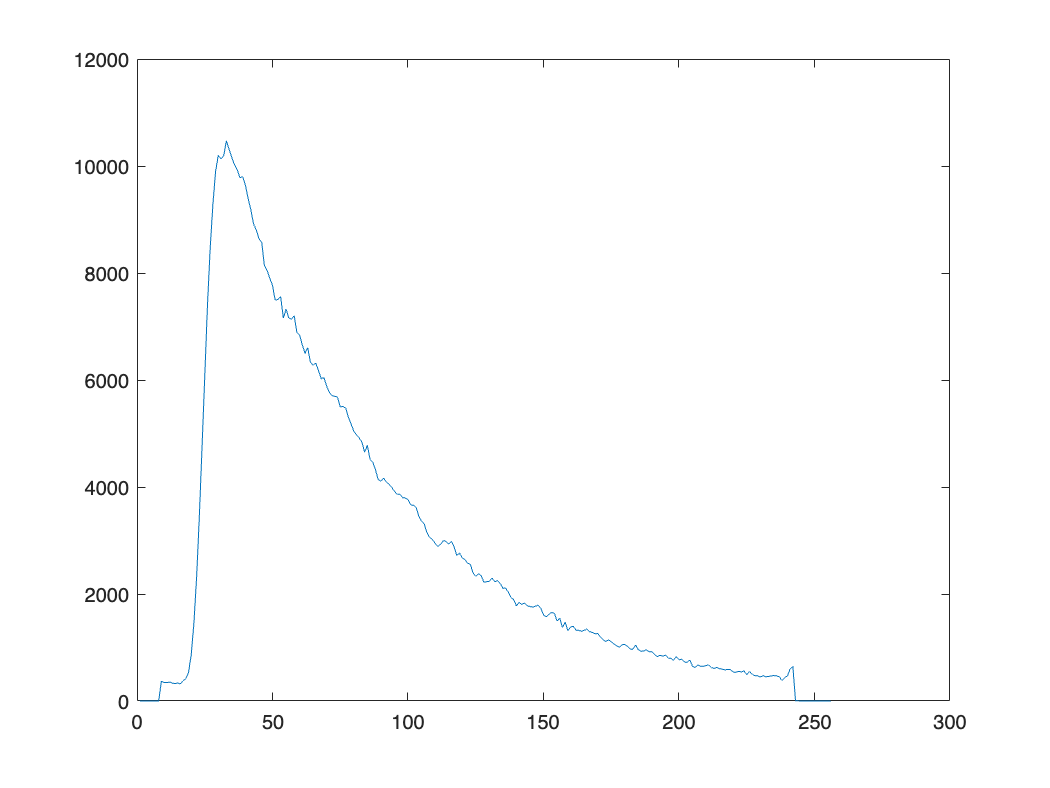

spc_lifetimes = spc_lifetimes_cycle1 + spc_lifetimes_cycle2;

figure
plot(spc_lifetimes)


spc.lifetimes{1} = spc_lifetimes'

spc = struct with fields:
         switchess: {[1×1 struct]  [1×1 struct]}
     GUI_switchess: [1×1 struct]
              fits: {[1×1 struct]}
          GUI_fits: [1×1 struct]
          filename: '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/20220914AChsensorHEK001FLIM083.mat'
              GUIS: [1×1 struct]
          datainfo: [1×1 struct]
               fit: [1×1 struct]
          switches: [1×1 struct]
         imageMods: {[256×128×128 double]}
      originalFile: 'C:\Users\User\Desktop\Pingchuan\2022Fall\20220914AChsensorHEK001\20220914AChsensorHEK001FLIM083.mat'
           SPCdata: [1×1 struct]
    imageModSlices: {}
       maxProjects: {[]}
         lifetimes: {[0 0 0 0 0 0 0 0 372 347 344 355 334 326 337 319 379 419 533 864 1456 2316 3446 4750 6062 7395 8463 9277 9900 10203 10130 10197 10471 10307 10155 10021 9930 9781 9801 9645 9393 9186 8919 8808 8640 8579 8144 8051 7905 7765 7489 … ]}
              size: [256 128 128]
          projects:

% move the corresponding prf to this folder, load this prf and do the
% fitting
cd(filepath)
copyfile /Volumes/yaochen/Active/Pingchuan/prf/prf_InsightBottomGreen_20220628.mat prf.mat

% after doing the fitting, output the fitting parameters

p1_ACh=spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p1_ACh = 0.9197

p2_ACh=spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p2_ACh = 0.0803

tau1_ACh=spc.fits{1,1}.beta2

tau1_ACh = 2.8628

tau2_ACh=spc.fits{1,1}.beta4

tau2_ACh = 0.3116

delta_peak_time=spc.fits{1,1}.beta5

delta_peak_time = 0.6231

SHG=spc.fits{1,1}.beta6

SHG = 0

samplesize_ACh=sum(spc.lifetimes{1})

samplesize_ACh = 734194

SHG_proportion=SHG/samplesize_ACh

SHG_proportion = 0

figureoffset=spc.switchess{1,1}.figOffset

figureoffset = 1.8797

backcorr=spc.fits{1,1}.backCorr

backcorr = 144.0748

chisq = spc.fits{1,1}.redchisq

chisq = 2.1800


% calculate the empirical lifetime from the histogram, considering the
% first 8 and last 8 channels are forced to be 0, and considering the
% fitting range.
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
nsPerPoint=spc.datainfo.psPerUnit/1000

nsPerPoint = 0.0489

range=round([spc.fits{1,1}.fitstart spc.fits{1,1}.fitend]/nsPerPoint)

range =     10   235


weight_n_lft=lft_steps.*spc.lifetimes{1}(range(1):range(2));
empirical_lft_ACh=sum(weight_n_lft)/sum(spc.lifetimes{1}(range(1):range(2)))

empirical_lft_ACh = 0.0488


% also export the histogram
n_exp_ACh=spc.lifetimes{1};
ACh_peak = find(n_exp_ACh == max(n_exp_ACh))

ACh_peak = 33


% calculate the empirical lifetime from the fitted curve


lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*spc.fits{1,1}.curve';
empirical_lft_ACh_curve=sum(weight_n_lft)/sum(spc.fits{1,1}.curve')

empirical_lft_ACh_curve = 3.4849

% save the fitting parameters
save('fitting_parameters.mat','p1_ACh','p2_ACh','tau1_ACh','tau2_ACh','delta_peak_time','SHG','samplesize_ACh','backcorr','empirical_lft_ACh','empirical_lft_ACh_curve')

% adjust the prf based on the delta peak time
% comment more the what the interpolation does and why doing that

load('prf.mat')
x=1:1:256;
prf_interp1=interp1(x,prf,x+(delta_peak_time/(12.5/256)),'linear');
prf_interp1(isnan(prf_interp1)) = 0;
prf_peak_ACh=find(prf_interp1==max(prf_interp1))

prf_peak_ACh = 25

find(prf==max(prf))

ans = 38

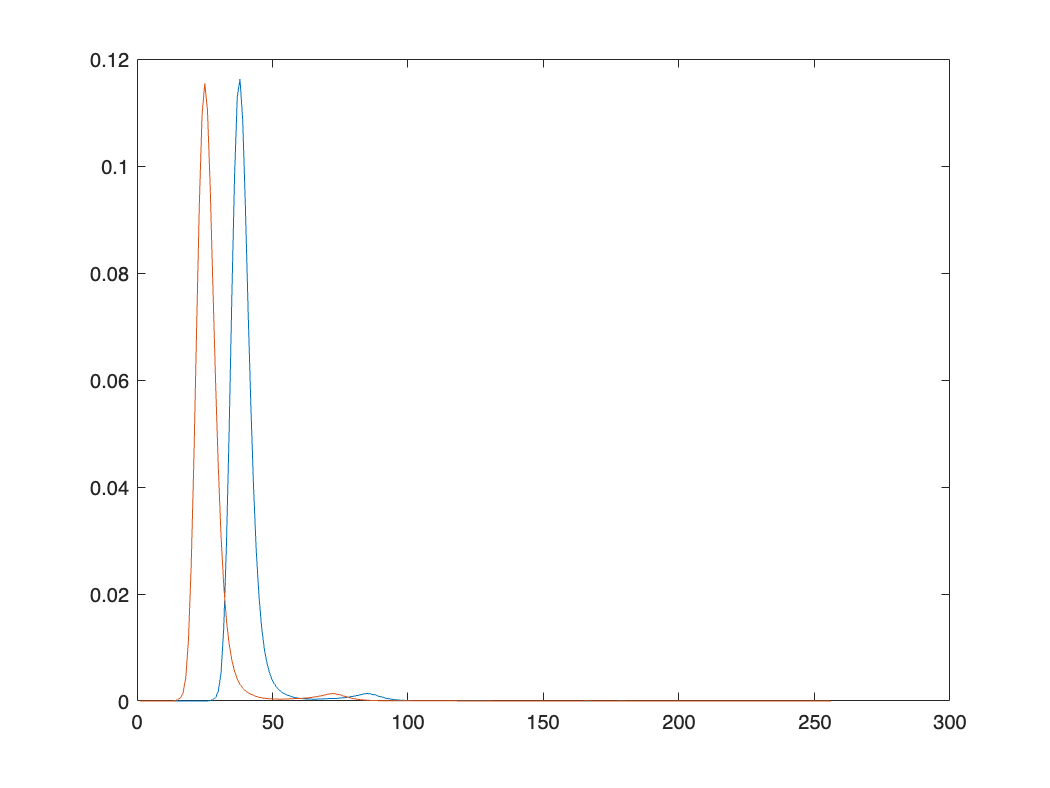


figure
plot(prf)
hold on
plot(prf_interp1)

% save this prf for future use
prf=prf_interp1;
prf_interp1_name='prf_ACh_interp1.mat';
save(prf_interp1_name,'prf')

% select a ROI or two, fix the offset at 0 for empirical lifetime
% find the corresponding functions to calculate the roi lifetime

global offset fixedoffset
fixedoffset=1;
offset=0;
spc_adjustTauOffset(1)

ACh_spc_file_cycle1 = [datapath stateYao.baseName 'FLIM0' num2str(ACh_acq_cycle1) '.mat']

ACh_spc_file_cycle1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/20220914AChsensorHEK001FLIM082.mat'

spc_openCurves(ACh_spc_file_cycle1)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/20220914AChsensorHEK001FLIM082.mat


icycle = 1;
iCell = 1;
photoncount_ACh_mean = Yao_calc_Projection(spc.projects{1}, stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle1}{iCell})

photoncount_ACh_mean = 195.5776

lft_ACh=Yao_calc_Lifetime(spc.projects{1}, spc.lifetimeMaps{1}, stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle1}{iCell})

lft_ACh = 3.4855

ROIsize_ACh=sum(sum(stateYao.I_ROI_stack_TopPixels{icycle}{ACh_index_cycle1}{iCell}))

ROIsize_ACh = 876

photoncount_ACh = photoncount_ACh_mean * ROIsize_ACh

photoncount_ACh = 171326

% go to another file of baseline condition
baseline_spc_file_cycle1 = [datapath stateYao.baseName 'FLIM0' num2str(baseline_acq_cycle1) '.mat']

baseline_spc_file_cycle1 = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/20220914AChsensorHEK001FLIM040.mat'

spc_openCurves(baseline_spc_file_cycle1)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK001_tio/20220914AChsensorHEK001FLIM040.mat


icycle = 1;
iCell = 1;
photoncount_baseline_mean = Yao_calc_Projection(spc.projects{1}, stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle1}{iCell})

photoncount_baseline_mean = 69.4491

lft_baseline=Yao_calc_Lifetime(spc.projects{1}, spc.lifetimeMaps{1}, stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle1}{iCell})

lft_baseline = 3.3151

ROIsize_baseline=sum(sum(stateYao.I_ROI_stack_TopPixels{icycle}{baseline_index_cycle1}{iCell}))

ROIsize_baseline = 864

photoncount_baseline = round(photoncount_baseline_mean * ROIsize_baseline)

photoncount_baseline = 60004

% Name the population of double exponential decay
PopulationName='ACh_population_20221221'

PopulationName = 'ACh_population_20221221'

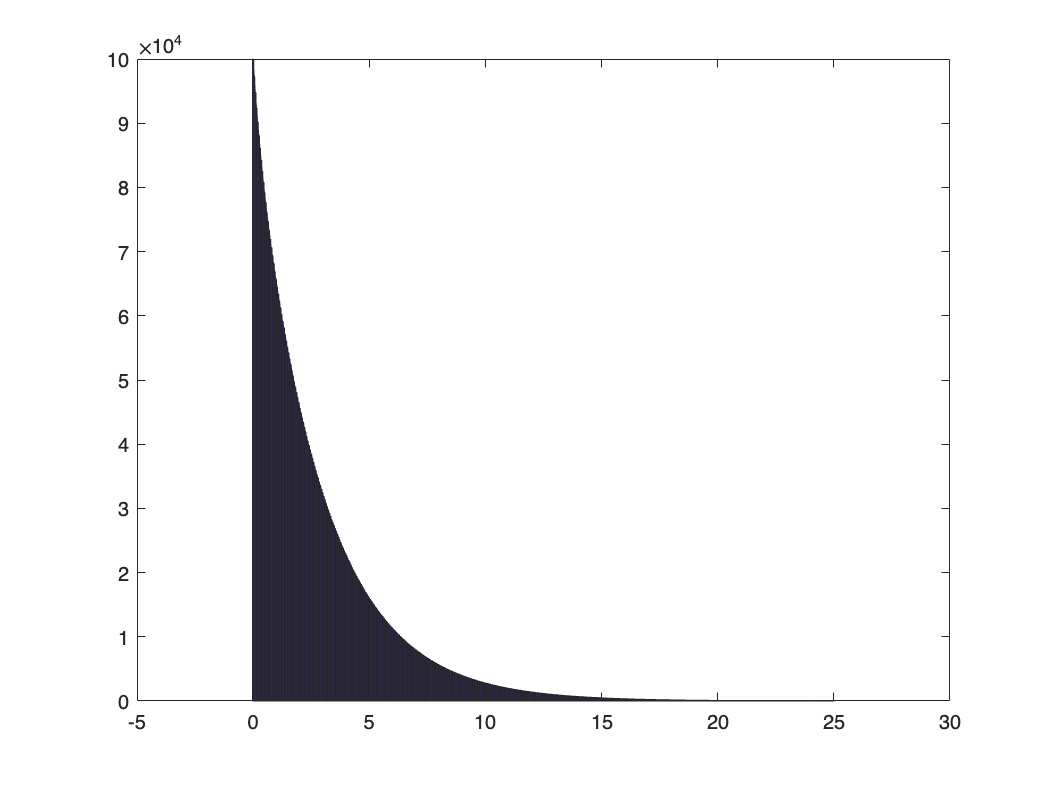

     5481945



% generate the double exponential population, no SHG added, 512 channels
GenPop512_Ach(100000,p1_ACh,p2_ACh,tau1_ACh,tau2_ACh,PopulationName)

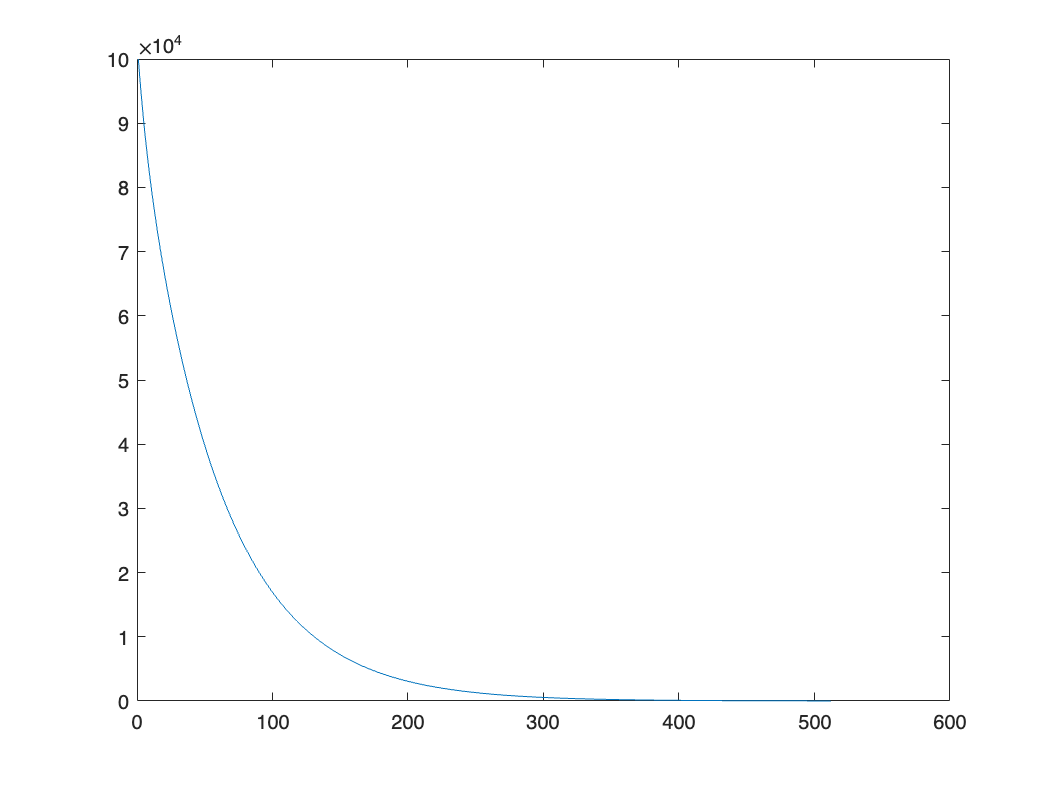

%% Test the population generated is ok. Calculate the analytical lft for each population

load(PopulationName)
xsim=linspace(0,25,512);
[n,xout]=hist(Population, xsim);
figure
plot(n)

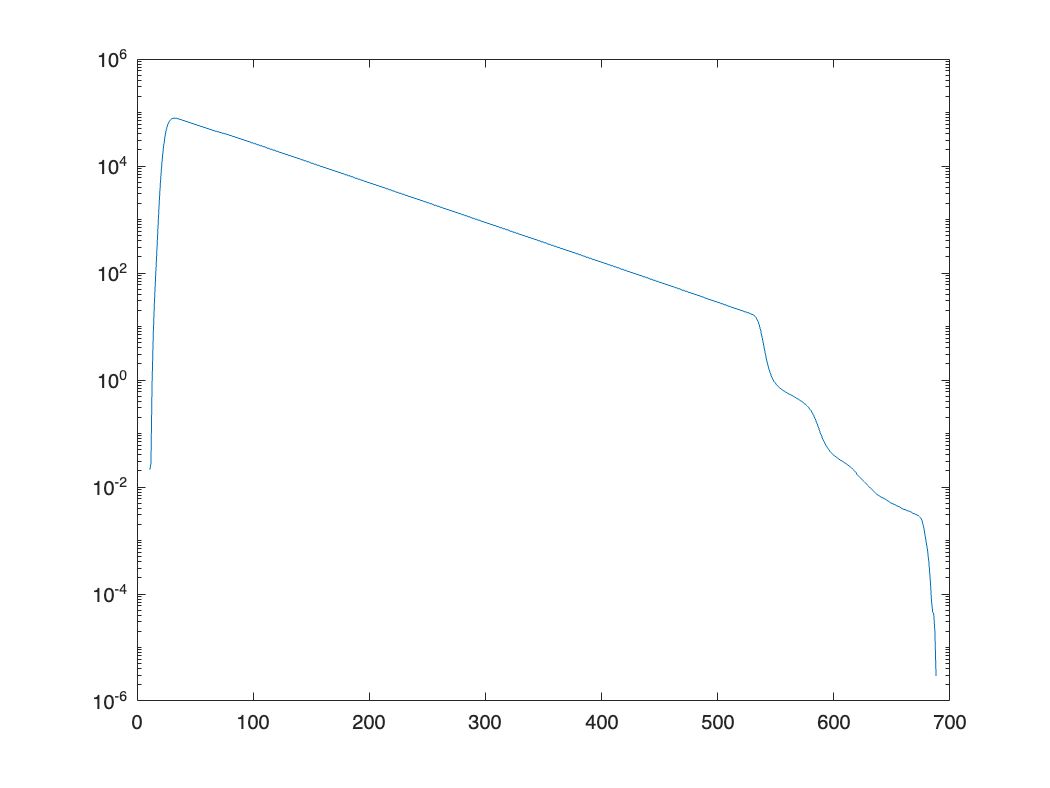


% convolute the double exponential curve use the new prf
conv_n=conv(n,prf);
figure % plot right after the convolution
semilogy(conv_n)

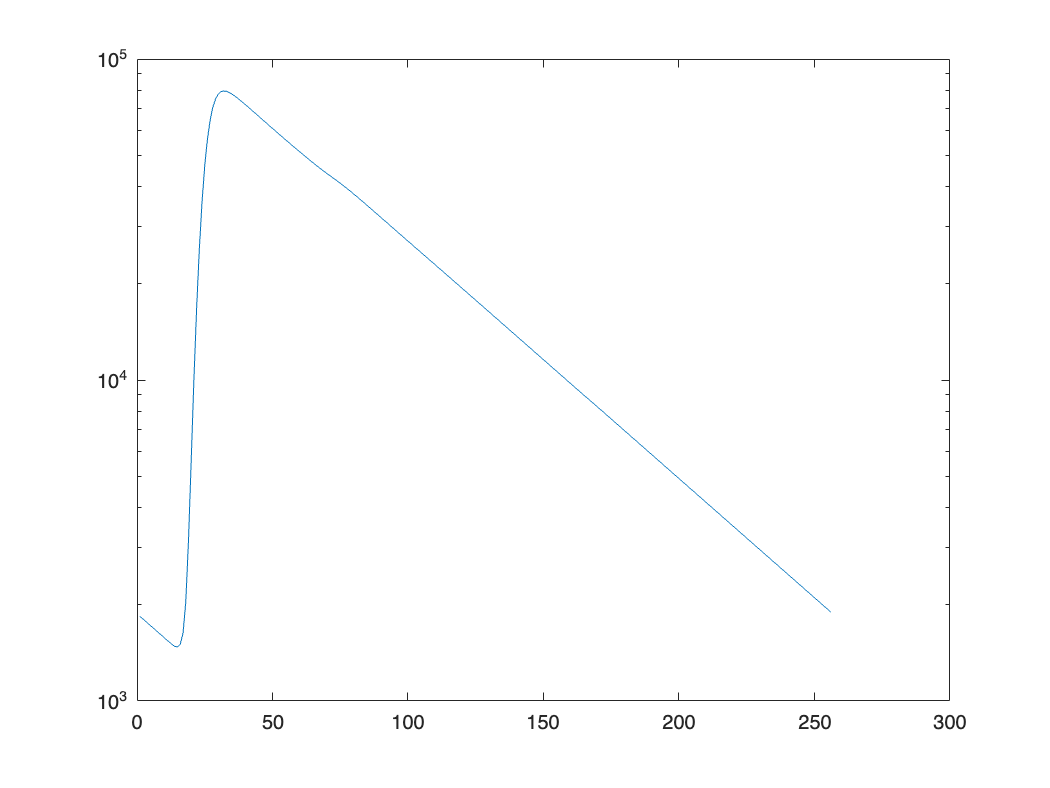


conv_n1=conv_n(257:512);
conv_n_final=conv_n(1:256)+conv_n1; % wrap around

figure
semilogy(conv_n_final) % plot after wrap around


% before background correction, calculate the empirical lifetime

lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*conv_n_final(range(1):range(2));
empirical_lft=sum(weight_n_lft)/sum(conv_n_final(range(1):range(2)))

empirical_lft = 3.3864


% add the background correction term, calculate the empirical lifetime
backcorr_ratio=backcorr/samplesize_ACh;
backcorr_ACh=sum(conv_n_final)*backcorr_ratio

backcorr_ACh = 1.0757e+03

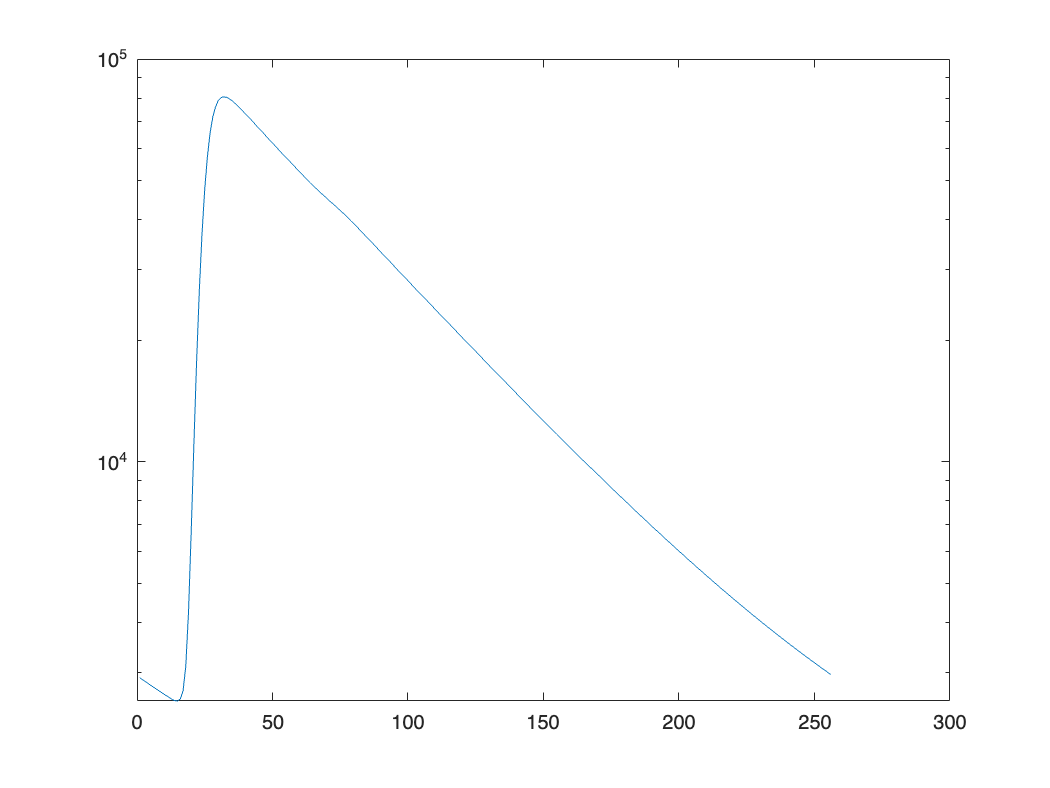

conv_n_final_corr=conv_n_final+backcorr_ACh;
figure
semilogy(conv_n_final_corr)


% from the fitted curve: empirical_lft_ACh_curve = 3.4850
weight_n_lft=lft_steps.*conv_n_final_corr(range(1):range(2));
empirical_lft_PopNoSHG=sum(weight_n_lft)/sum(conv_n_final_corr(range(1):range(2)))

empirical_lft_PopNoSHG = 3.4790



% so generation of the population is good. Then move to simulation

copyfile /Volumes/yaochen/Active/Pingchuan/simulation/AutoFluo0917.mat autofluorescence.mat

load('autofluorescence.mat')

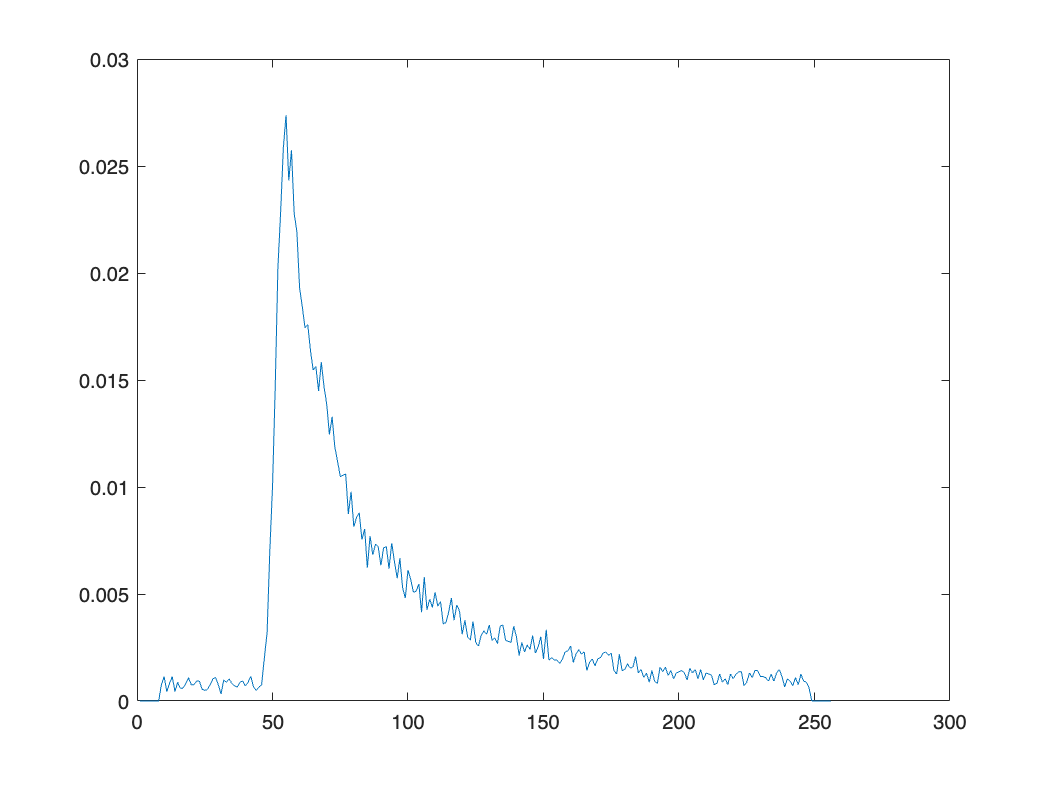

figure
plot(AutoFluo0917)


autofluo_peak = find(AutoFluo0917 == max(AutoFluo0917))

autofluo_peak = 55

AutoFluo0917_original = AutoFluo0917;
ACh_peak

ACh_peak = 33

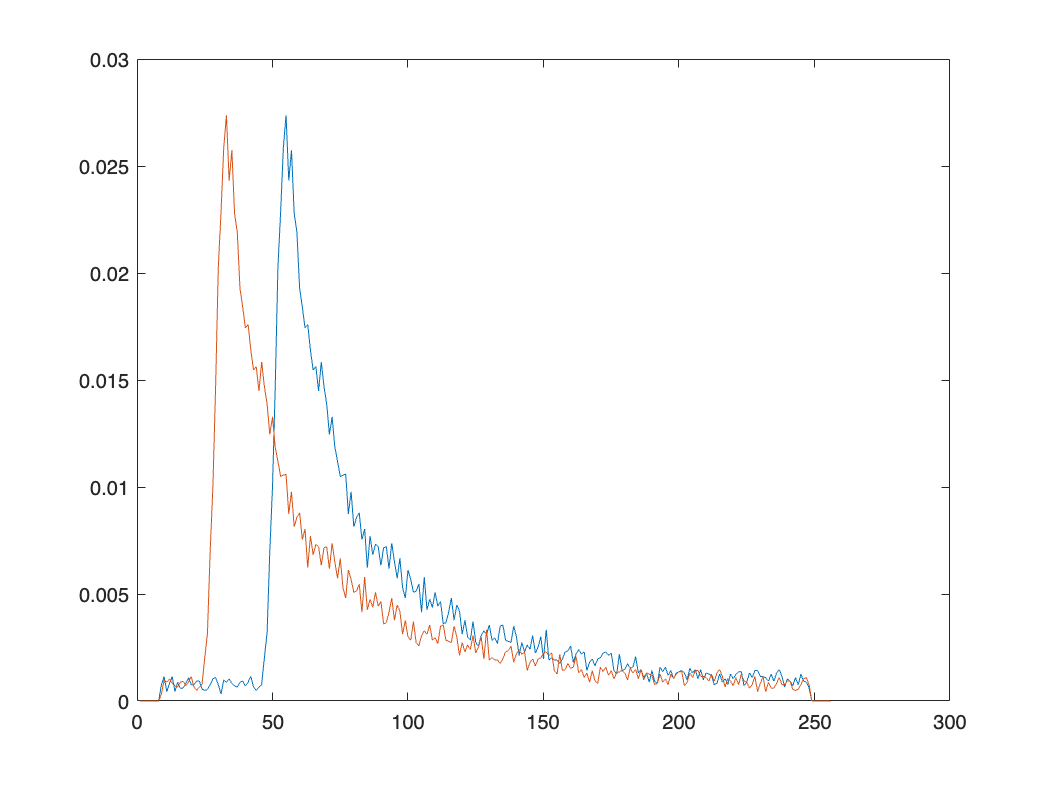

AutoFluo0917(9:248-(autofluo_peak - ACh_peak)) = AutoFluo0917_original(9+(autofluo_peak - ACh_peak):248);
AutoFluo0917(248-(autofluo_peak - ACh_peak)+1:248) = AutoFluo0917_original(9:9+(autofluo_peak - ACh_peak)-1);

figure
plot(AutoFluo0917_original)
hold on
plot(AutoFluo0917)

Autofluo_shifted = 'autofluorescence_shifted.mat'

Autofluo_shifted = 'autofluorescence_shifted.mat'


save(Autofluo_shifted, 'AutoFluo0917')

lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*AutoFluo0917(range(1):range(2));
empirical_lft_autofluo=sum(weight_n_lft)/sum(AutoFluo0917(range(1):range(2)))

empirical_lft_autofluo = 3.1909

% test the simulation, if no dark count, no afterpulse, no
% autofluorescence, simulate and then add background correction, the
% lifetime should be similiar to the fitted curve
DC=0;
afterpulse=0;
AF=0;
SaveName='test_sim.mat'

SaveName = 'test_sim.mat'

FLIMsim512_Ach(samplesize_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName)

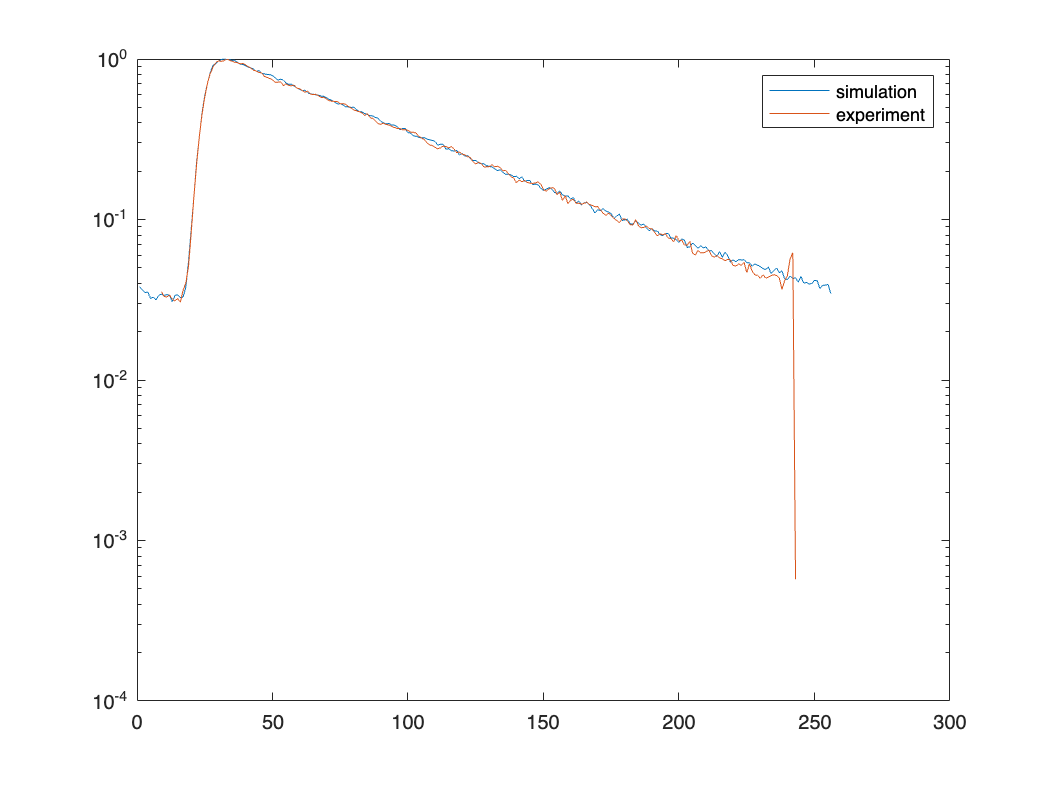

load(SaveName)
figure
% semilogy(n_final)

n_final=n_final+backcorr;
% hold on
semilogy(n_final/(max(n_final)))

hold on
semilogy(n_exp_ACh/max(n_exp_ACh))
legend('simulation','experiment')


lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*n_final(range(1):range(2));
empirical_lft_curveonly=sum(weight_n_lft)/sum(n_final(range(1):range(2)))

empirical_lft_curveonly = 3.4804


% from the fitted curve: empirical_lft_ACh_curve = 3.8608
% so the simulation should be good.


% Now do the real simulation, for real simulaition, for autofluorescence should have already include the dark count and SHG term
% So I'll use the population without SHG, and add no dark count to the
% simulated sample.

% first start with no autofluorescence, no after pulse
% use photoncount from the ROI for simulation

DC=0;
AF=0;
afterpulse=0;
mkdir('ACh')
mkdir('baseline')

for i=1:100
    SaveName=['ACh/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:100
    SaveName=['baseline/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh=[];
simulated_lft_baseline=[];

for i=1:100
    SaveName=['ACh/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline(i)=empirical_lft_baseline;
end

mean(simulated_lft_ACh)

ans = 3.4794

mean(simulated_lft_baseline)

ans = 3.4788

% then add afterpulse as 0.8% of the total
DC=0;
AF=0;
afterpulse=0.008;
mkdir('ACh_afterpulse')

mkdir('baseline_afterpulse')


for i=1:100
    SaveName=['ACh_afterpulse/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

for i=1:100
    SaveName=['baseline_afterpulse/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh_AP=[];
simulated_lft_baseline_AP=[];

for i=1:100
    SaveName=['ACh_afterpulse/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh_AP(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline_afterpulse/',num2str(i),'.mat'];
    load(SaveName)
%     n_final=n_final+backcorr_baseline*(photoncount_baseline/samplesize_baseline);
    lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline_AP(i)=empirical_lft_baseline;
end

mean(simulated_lft_ACh_AP)

ans = 3.4017

mean(simulated_lft_baseline_AP)

ans = 3.4023

% then add autofluorescence, based on the ROIsize
DC=0;
AF=round(20000*ROIsize_ACh/(128*128))

AF = 1069

afterpulse=0;
mkdir('ACh_afterpulse_AF')
mkdir('baseline_afterpulse_AF')


for i=1:100
    SaveName=['ACh_afterpulse_AF/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_ACh, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence_shifted.mat',SaveName);
end

for i=1:100
    SaveName=['baseline_afterpulse_AF/',num2str(i),'.mat'];
    FLIMsim512_Ach(photoncount_baseline, DC, AF, afterpulse, PopulationName, prf_interp1_name, 'autofluorescence_shifted.mat',SaveName);
end

% load the simulated data, calculate the lifetimes
simulated_lft_ACh_AF=[];
simulated_lft_baseline_AF=[];

for i=1:100
    SaveName=['ACh_afterpulse_AF/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_ACh/samplesize_ACh);
    lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_ACh=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_ACh_AF(i)=empirical_lft_ACh;
end

for i=1:100
    SaveName=['baseline_afterpulse_AF/',num2str(i),'.mat'];
    load(SaveName)
    n_final=n_final+backcorr*(photoncount_baseline/samplesize_ACh);
    lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
    weight_n_lft=lft_steps.*n_final(range(1):range(2));
    empirical_lft_baseline=sum(weight_n_lft)/sum(n_final(range(1):range(2)));
    simulated_lft_baseline_AF(i)=empirical_lft_baseline;
end


mean(simulated_lft_ACh_AF)

ans = 3.4766

mean(simulated_lft_baseline_AF)

ans = 3.4738

load('autofluorescence.mat')
AF=20000;
n_norm=conv_n_final/sum(conv_n_final)

n_norm =     0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0006    0.0010    0.0018    0.0030    0.0047    0.0065    0.0085    0.0103    0.0118    0.0129    0.0137    0.0142    0.0144    0.0145    0.0145    0.0144    0.0142    0.0140    0.0138    0.0136    0.0134    0.0132    0.0129    0.0127    0.0125    0.0123    0.0121    0.0119    0.0117    0.0115    0.0113    0.0111


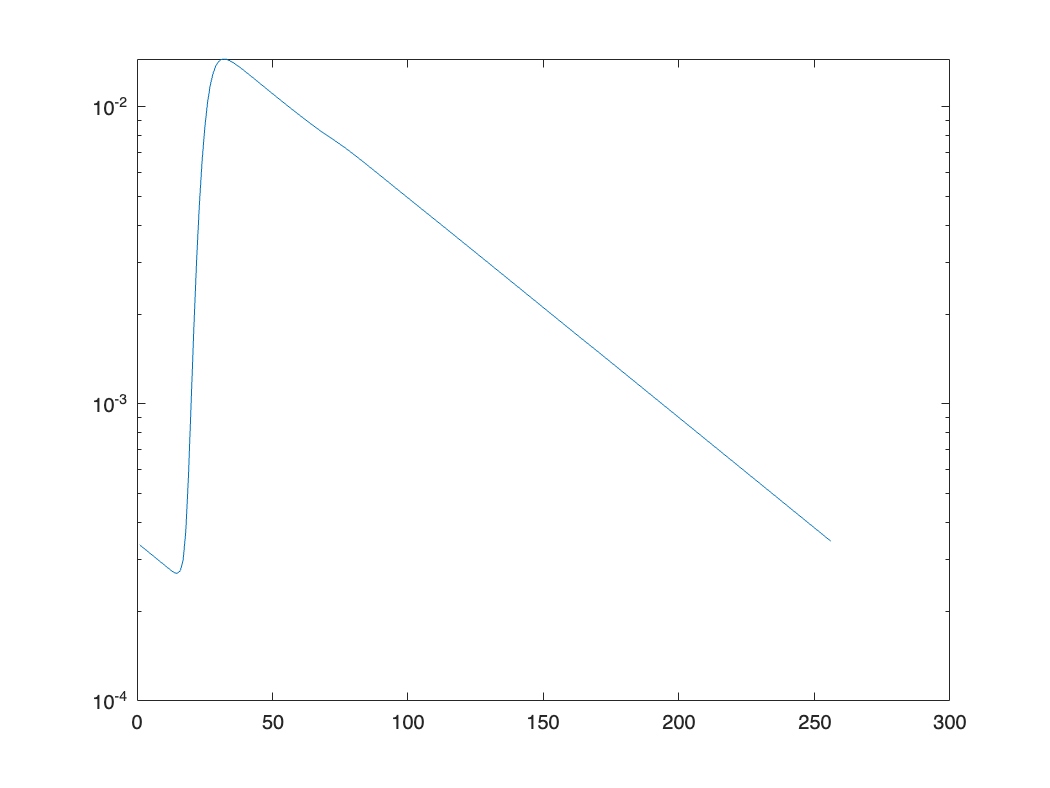

figure
semilogy(n_norm)


n_ACh=n_norm*photoncount_ACh+AutoFluo0917*AF*ROIsize_ACh/(128*128)+(zeros(1,256)+backcorr_ratio*photoncount_ACh)

n_ACh = 1.0e+03 *

    0.0911    0.0901    0.0892    0.0882    0.0873    0.0864    0.0855    0.0846    0.0846    0.0841    0.0825    0.0821    0.0817    0.0803    0.0807    0.0813    0.0852    0.0982    0.1331    0.2097    0.3470    0.5568    0.8333    1.1545    1.4872    1.7964    2.0545    2.2488    2.3829    2.4650    2.5061    2.5198    2.5131    2.4939    2.4664    2.4341    2.3990    2.3626    2.3252    2.2874    2.2499    2.2130    2.1758    2.1393    2.1036    2.0685    2.0352    2.0025    1.9733    1.9439


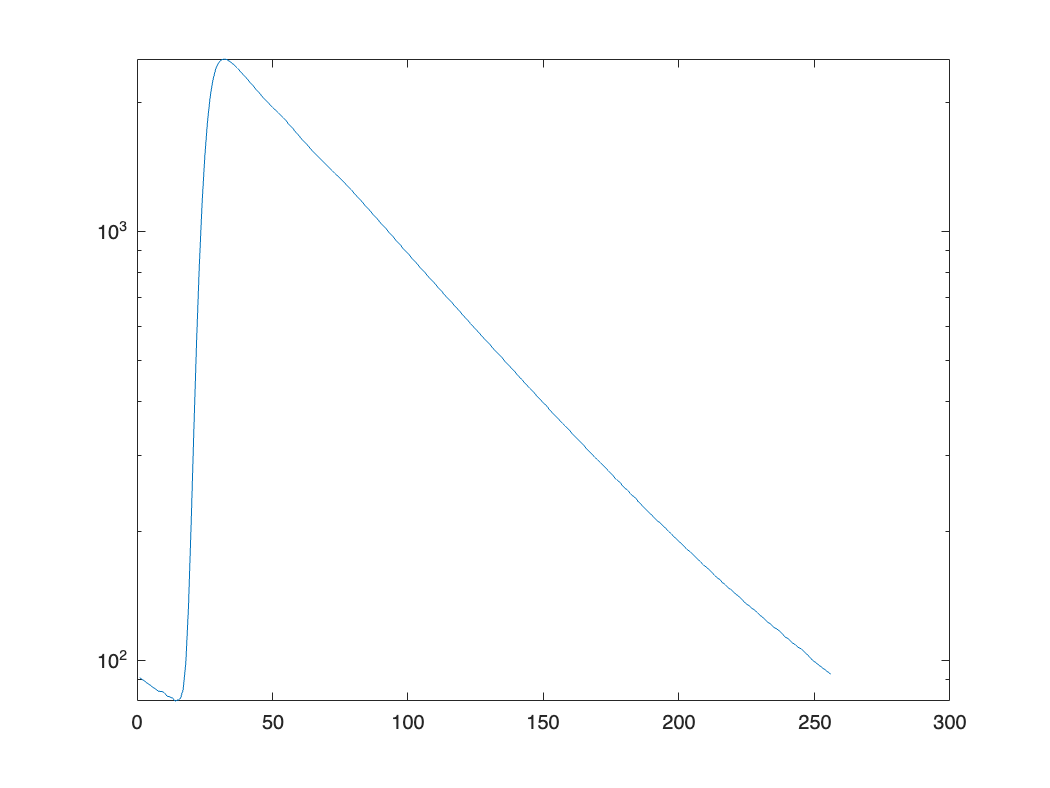

figure
semilogy(n_ACh)


n_baseline=n_norm*photoncount_baseline+AutoFluo0917*AF*ROIsize_baseline/(128*128)+(zeros(1,256)+backcorr_ratio*photoncount_baseline)

n_baseline =    31.8992   31.5585   31.2235   30.8941   30.5701   30.2515   29.9382   29.6301   30.1341   30.2398   29.1982   29.3141   29.3870   28.4268   28.8474   28.8896   30.2517   34.9393   47.3707   73.9551  122.0348  195.6319  292.4872  404.7229  521.1939  629.5427  720.0823  788.3010  835.3205  863.8316  877.9517  883.1794  880.7486  874.1492  864.3727  852.9986  840.6423  828.0590  815.0092  801.5962  788.5992  775.8542  762.4702  749.5735  737.2111  724.9816  714.1774  703.5135  695.8764  687.6027


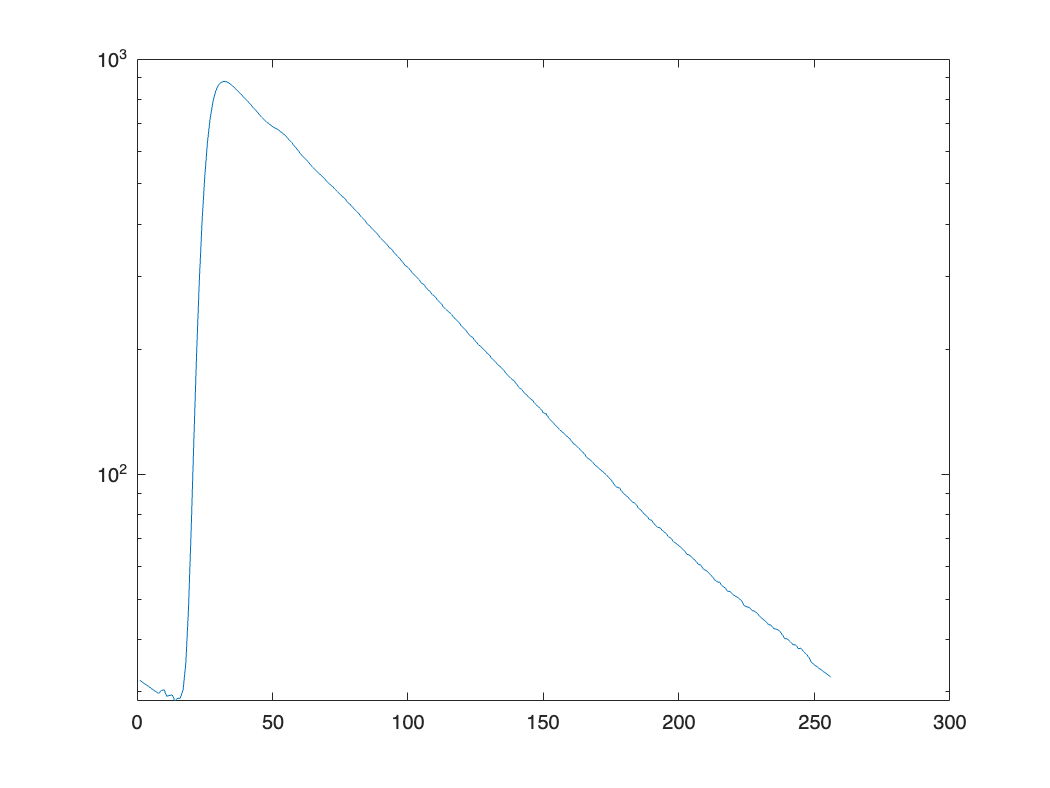

figure
semilogy(n_baseline)

% empirical_lft_ACh = 5.1762
lft_steps=(1:1:(range(2)-range(1)+1))*12.5/256;
weight_n_lft=lft_steps.*n_ACh(range(1):range(2));
empiricallft_ACh=sum(weight_n_lft)/sum(n_ACh(range(1):range(2)))

empiricallft_ACh = 3.4824


% empirical_lft_baseline = 5.0480
weight_n_lft=lft_steps.*n_baseline(range(1):range(2));
empiricallft_baseline=sum(weight_n_lft)/sum(n_baseline(range(1):range(2)))

empiricallft_baseline = 3.4885

save('simulation_20221218.mat')